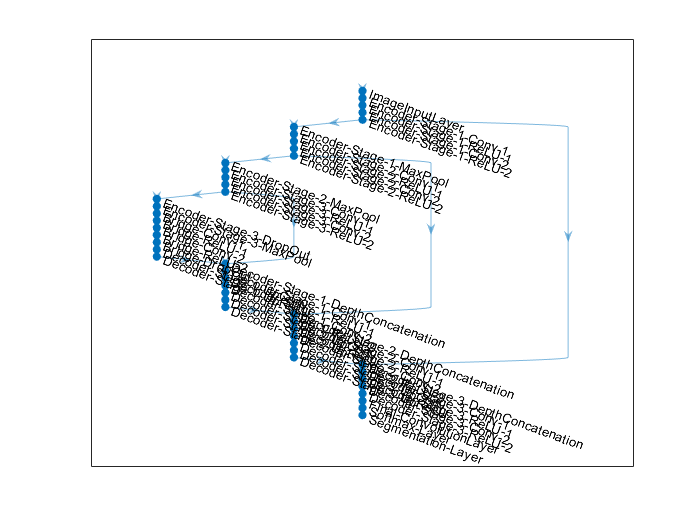

clc;
clear all;

imageSize = [480 640 3];

numClasses = 5;
encoderDepth = 3;
lgraph = unetLayers(imageSize,numClasses,'EncoderDepth',encoderDepth);
plot(lgraph) % Plot the network


% % Plot()
% dataSetDir= fullfile(toolboxdir('vision'),'visiondata','triangleImages');

% 2) Train U-Net for semantic segmentation

## Load training images and pixel labels


dataSetDir = fullfile(toolboxdir('vision'),'visiondata','triangleImages');
imageDir = fullfile(dataSetDir,'trainingImages');
labelDir = fullfile(dataSetDir,'trainingLabels');
%% Create an imageDatastore object to store the training images.
imds = imageDatastore(imageDir);
%% Define the class names and their associated label IDs.
classNames = ["triangle","background"];
labelIDs   = [255 0];
%%
% Create a pixelLabelDatastore object to store the ground truth pixel 
% labels for the training images.
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);
%% Crating the U-Net network
imageSize = [32 32];
numClasses = 2;
lgraph = unetLayers(imageSize, numClasses)

lgraph =   LayerGraph with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


ds = combine(imds,pxds); % Datastore for training the network.
%% Training options
options = trainingOptions('sgdm', ...
    'InitialLearnRate',1e-2, ...
    'MaxEpochs',30, ...
    'VerboseFrequency',10);
%% Train the network
net = trainNetwork(ds,lgraph,options)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:10 |       75.57% |       2.4341 |          0.0100 |
|      10 |          10 |       00:01:20 |        5.34% |          NaN |          0.0100 |
|      20 |          20 |       00:02:21 |        5.34% |          NaN |          0.0100 |
|      30 |          30 |       00:03:21 |        5.34% |          NaN |          0.0100 |
|========================================================================================|


net =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}
